## Setup

First, we must define the Denavit-Hartenberg parameters. These describe the geometry of the robot arm. They are measured from the arm's CAD.

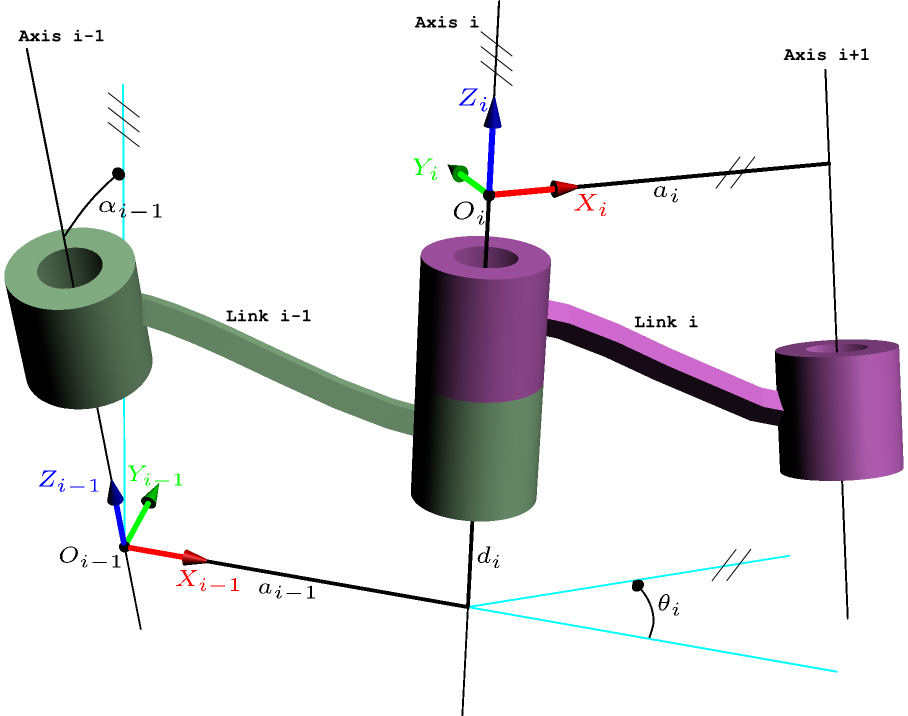

clear

theta = sym("theta",[1,6]);
assume(theta, "real")

alpha_0 = 0;
a_0     = 0;
d_1     = 240.92/1000;
theta_1 = theta(1);

alpha_1 = sym(pi/2);
a_1     = 3.48/1000;
d_2     = 0;
theta_2 = theta(2);

alpha_2 = 0;
a_2     = 560/1000;
d_3     = 0;
theta_3 = theta(3);

alpha_3 = 0;
a_3     = 415/1000;
d_4     = 0;
theta_4 = theta(4);

alpha_4 = sym(-pi/2);
a_4     = 71.71/1000;
d_5     = 25.17/1000;
theta_5 = theta(5)+(pi/2);

alpha_5 = sym(pi/2);
a_5     = 0;
d_6     = 0;
theta_6 = theta(6);

L6 = 217.44/1000;


## Calculate Transfer Matrix

Once the Denavit-Hartenberg parameters have been assigned, they can be used to calculate transfer matrices between each axis.

T_1_to_0 = DH_vals_to_T(alpha_0,a_0,d_1,theta_1);
T_2_to_1 = DH_vals_to_T(alpha_1,a_1,d_2,theta_2);
T_3_to_2 = DH_vals_to_T(alpha_2,a_2,d_3,theta_3);
T_4_to_3 = DH_vals_to_T(alpha_3,a_3,d_4,theta_4);
T_5_to_4 = DH_vals_to_T(alpha_4,a_4,d_5,theta_5);
T_6_to_5 = DH_vals_to_T(alpha_5,a_5,d_6,theta_6);
T_H_to_6 = [eye(3) [0; 0; L6]; 0 0 0 1];

T_H_to_6 =     1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000    0.2174
         0         0         0    1.0000


These transfer matrices can then be multiplied to obtain a single transfer matrix from the hand's reference frame to the base's reference frame.

T_H_to_0 = T_1_to_0*T_2_to_1*T_3_to_2*T_4_to_3*T_5_to_4*T_6_to_5*T_H_to_6;

To verify the results look correct, we can plot the arm to visually inspect the results.

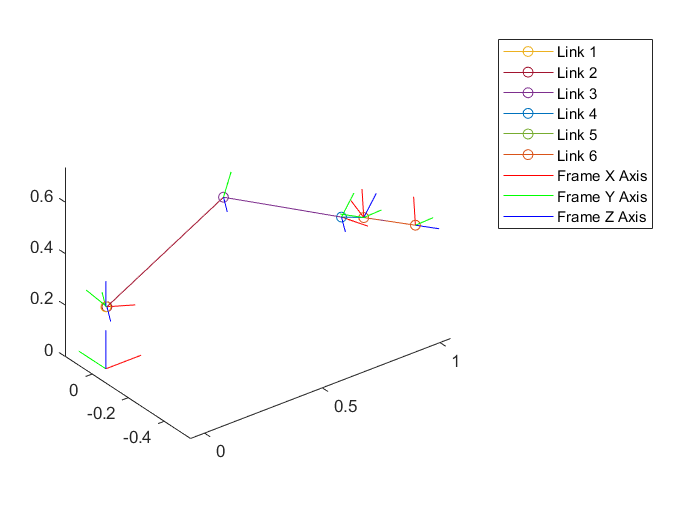

theta_vals = deg2rad([-30,45,-60,-10,20,40]);
T_1_to_0_v = double(subs(T_1_to_0,[sym("theta1"),sym("theta2"),sym("theta3"),sym("theta4"),sym("theta5"),sym("theta6")],theta_vals));
T_2_to_1_v = double(subs(T_2_to_1,[sym("theta1"),sym("theta2"),sym("theta3"),sym("theta4"),sym("theta5"),sym("theta6")],theta_vals));
T_3_to_2_v = double(subs(T_3_to_2,[sym("theta1"),sym("theta2"),sym("theta3"),sym("theta4"),sym("theta5"),sym("theta6")],theta_vals));
T_4_to_3_v = double(subs(T_4_to_3,[sym("theta1"),sym("theta2"),sym("theta3"),sym("theta4"),sym("theta5"),sym("theta6")],theta_vals));
T_5_to_4_v = double(subs(T_5_to_4,[sym("theta1"),sym("theta2"),sym("theta3"),sym("theta4"),sym("theta5"),sym("theta6")],theta_vals));
T_6_to_5_v = double(subs(T_6_to_5,[sym("theta1"),sym("theta2"),sym("theta3"),sym("theta4"),sym("theta5"),sym("theta6")],theta_vals));
plot_arm({T_1_to_0_v,T_2_to_1_v,T_3_to_2_v,T_4_to_3_v,T_5_to_4_v,T_6_to_5_v,T_H_to_6})

## Forward Kinematics

After we have obtained the transfer matrix, we can extract the relavant forward kinematic parameters from the matrix. The x,y, and z values can be extracted directly, while the alpha,beta, and gamma rotations must be found from the rotation component of the matrix.

x = T_H_to_0(1,4);
y = T_H_to_0(2,4);
z = T_H_to_0(3,4);

[alpha,beta,gamma] = Inv_Euler_ZYX(T_H_to_0(1:3,1:3));

fwd_kin = [x;y;z;alpha;beta;gamma];
fwd_kin = simplify(fwd_kin,"Steps",10);

forward_kinematics = matlabFunction(fwd_kin,"File","forward_kinematics","Vars",{theta});

## Calculate Jacobian

Once we have calculated these values, we can calculate the Jacobian of the forward kinematics equations.


$${\;}^0 J_H \left(\overrightarrow{\theta} \right)=\left\lbrack \begin{array}{cccccc}
\frac{\delta x}{\delta \theta_1 } & \frac{\delta x}{\delta \theta_2 } & \frac{\delta x}{\delta \theta_3 } & \frac{\delta x}{\delta \theta_4 } & \frac{\delta x}{\delta \theta_5 } & \frac{\delta x}{\delta \theta_6 }\\
\frac{\delta y}{\delta \theta_1 } & \frac{\delta y}{\delta \theta_2 } & \frac{\delta y}{\delta \theta_3 } & \frac{\delta y}{\delta \theta_4 } & \frac{\delta y}{\delta \theta_5 } & \frac{\delta y}{\delta \theta_6 }\\
\frac{\delta z}{\delta \theta_1 } & \frac{\delta z}{\delta \theta_2 } & \frac{\delta z}{\delta \theta_3 } & \frac{\delta z}{\delta \theta_4 } & \frac{\delta z}{\delta \theta_5 } & \frac{\delta z}{\delta \theta_6 }\\
\frac{\delta \alpha }{\delta \theta_1 } & \frac{\delta \alpha }{\delta \theta_2 } & \frac{\delta \alpha }{\delta \theta_3 } & \frac{\delta \alpha }{\delta \theta_4 } & \frac{\delta \alpha }{\delta \theta_5 } & \frac{\delta \alpha }{\delta \theta_6 }\\
\frac{\delta \beta }{\delta \theta_1 } & \frac{\delta \beta }{\delta \theta_2 } & \frac{\delta \beta }{\delta \theta_3 } & \frac{\delta \beta }{\delta \theta_4 } & \frac{\delta \beta }{\delta \theta_5 } & \frac{\delta \beta }{\delta \theta_6 }\\
\frac{\delta \gamma }{\delta \theta_1 } & \frac{\delta \gamma }{\delta \theta_2 } & \frac{\delta \gamma }{\delta \theta_3 } & \frac{\delta \gamma }{\delta \theta_4 } & \frac{\delta \gamma }{\delta \theta_5 } & \frac{\delta \gamma }{\delta \theta_6 }
\end{array}\right\rbrack$$
 

The Jacobian is useful since it allows us to relate the world-space rates to the joint-space rates.


$$\frac{\delta }{\delta t}\left\lbrack \begin{array}{c}
x\\
y\\
z\\
\alpha \\
\beta \\
\gamma 
\end{array}\right\rbrack ={\;}^0 J_H \;\left(\frac{\delta }{\delta t}\left\lbrack \begin{array}{c}
\theta_1 \\
\theta_2 \\
\theta_3 \\
\theta_4 \\
\theta_5 \\
\theta_6 
\end{array}\right\rbrack \right)$$


Even more usefully, the Jacobian can be easily inverted, allowing the joint-space rates to be found from the world-space rates. 


$$\frac{\delta }{\delta t}\left\lbrack \begin{array}{c}
\theta_1 \\
\theta_2 \\
\theta_3 \\
\theta_4 \\
\theta_5 \\
\theta_6 
\end{array}\right\rbrack ={{\;}^0 J_H }^{-1} \;\left(\frac{\delta }{\delta t}\left\lbrack \begin{array}{c}
x\\
y\\
z\\
\alpha \\
\beta \\
\gamma 
\end{array}\right\rbrack \right)$$


This calculation takes a few minutes!

J = jacobian([x,y,z,alpha,beta,gamma],theta);
J = simplify(J,"Steps",100);

Once the calculation is complete, we can export the symbolic variable to a function that allows the numeric values to be computed quickly and easily.

J_func = matlabFunction(J,"File","J_func.m");

After this the file J_func.m contains the generated code to calculate the jacobian. This can be rewritten in another language to do the calculations elsewhere.

## Example of using the Jacobian

This code will need to be implemented in python on the arm's pi, but an overview will be given here.

at some time $t$, the arm's joint angles are $\theta \left(t\right)$. We would like to move the gripper forward in the y direction at 1 units per second, with no other cartesian movement or rotation. This means our desired movement vector is:

 
$${\dot{\mathit{\mathbf{X}}} }_{\mathrm{des}} =\left\lbrack \begin{array}{c}
0\\
1\\
0\\
0\\
0\\
0
\end{array}\right\rbrack$$


We can use the inverse of the Jacobian to find the needed joint angle rates


$$\frac{d\theta }{dt}={J\left(\theta \left(t\right)\right)}^{-1} \;{\mathit{\mathbf{X}}}_{\mathrm{des}}$$


These joint angle rates are only valid at $\theta \left(t\right)$, so $\frac{d\theta }{dt}$ must be recalculated at each timestep of the control loop as $\theta \left(t\right)$ changes, which means ${J\left(\theta \left(t\right)\right)}^{-1}$ also changes.

(Note: using the Moore–Penrose pseudo-inverse (pinv in MATLAB, numpy.linalg.pinv in python) instead of the normal inverse (inv in MATLAB, numpy.linalg,inv in python) allows the IK to be robust to singular configurations.)

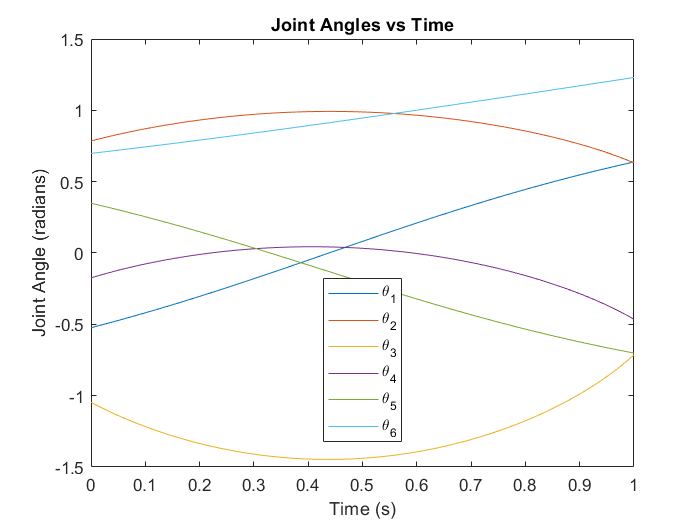

X_dot_des = [0;1;0;0;0;0]; % Desired world rates
theta_t = [];
theta_t(:,1) = theta_vals.'; % Initial angles
X_t = [];
X_t(:,1) = forward_kinematics(theta_t(:,1).'); % Initial pose
T = 1; % Simulation time
iter = 1000; % Number of iterations
dt = T/iter; % Timestep

for k = 1:iter
    t = k*dt; % Calculate time 
    J_val = J_func(theta_t(1,k),theta_t(2,k),theta_t(3,k),theta_t(4,k),theta_t(5,k),theta_t(6,k)); % Calculate Jacobian
    J_pinv = pinv(J_val); % Invert Jacobian
    
    theta_rates = J_pinv * X_dot_des; % Calculate joint rates

    % Replace the line below with commanding the new joint rates, waiting
    % for a moment, then reading the joint angles.
    theta_t(:,k+1) = theta_t(:,k) + theta_rates*dt; % Move Arm (Simulation only)
    
    X_t(:,k+1) = forward_kinematics(theta_t(:,k+1).'); % Calculate new world position with forward kinematics

end

figure()
plot((0:iter)*dt,theta_t)
title("Joint Angles vs Time");
xlabel("Time (s)");
ylabel("Joint Angle (radians)");
legend(["\theta_1" "\theta_2" "\theta_3" "\theta_4" "\theta_5" "\theta_6"],"Location","best")

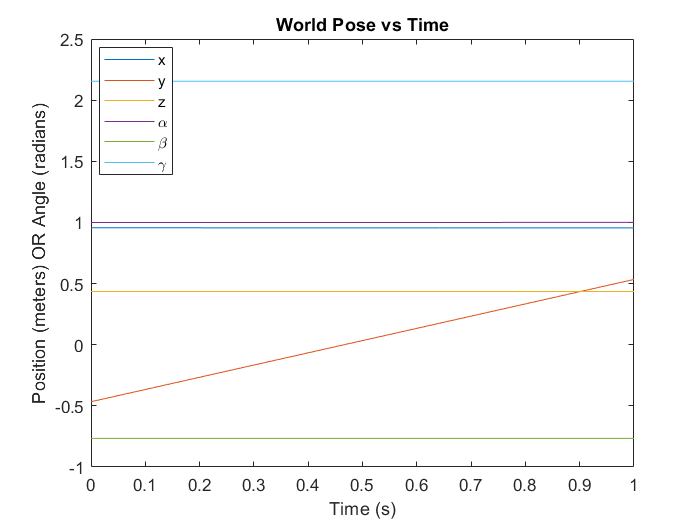

figure()
plot((0:iter)*dt,X_t)
title("World Pose vs Time");
xlabel("Time (s)");
ylabel("Position (meters) OR Angle (radians)");
legend(["x" "y" "z" "\alpha" "\beta" "\gamma"],"Location","best")

## Appendix: Calculation Functions

function R = Euler_ZYX(alpha,beta,gamma)
%From Assignment 1
    R_z = [cos(alpha) -sin(alpha) 0; sin(alpha) cos(alpha) 0; 0 0 1];
    R_y = [cos(beta) 0 sin(beta); 0 1 0; -sin(beta) 0 cos(beta)];
    R_x = [1 0 0; 0 cos(gamma) -sin(gamma); 0 sin(gamma) cos(gamma)];
    R = R_z*R_y*R_x;
end

function [alpha,beta,gamma] = Inv_Euler_ZYX(R,posOrNeg)
%From Assignment 1
    if nargin == 1 || posOrNeg == 0
        posOrNeg = 1;
    end
    posOrNeg = sign(posOrNeg);
    
    beta = atan2(-R(3,1),posOrNeg*sqrt(R(1,1)^2+R(2,1)^2));
    if cos(beta)==0 
        alpha = 0;
        gamma = sign(beta)*atan2(R(1,2),R(2,2));
    else
        alpha = atan2(R(2,1)/cos(beta),R(1,1)/cos(beta));
        gamma = atan2(R(3,2)/cos(beta),R(3,3)/cos(beta));
    end
end

function T = DH_vals_to_T(alpha_im1,a_im1,d_i,theta_i)
    T = [cos(theta_i) -sin(theta_i) 0 a_im1;...
        sin(theta_i)*cos(alpha_im1) cos(theta_i)*cos(alpha_im1) -sin(alpha_im1) -sin(alpha_im1)*d_i;...
        sin(theta_i)*sin(alpha_im1) cos(theta_i)*sin(alpha_im1) cos(alpha_im1) cos(alpha_im1)*d_i;...
        0 0 0 1];
end

function plot_arm(AxesCells, frameSize)
    if nargin == 1 || frameSize == 0
        frameSize = 1;
    end
    
    legendArray = {};
    figure();
    clf
    hold on;
    baseTransform = eye(4);
    plot_tform(baseTransform,"FrameSize",0.15*frameSize);
    armTransform = AxesCells{1};
    plot_tform(armTransform,"FrameSize",0.1*frameSize);
    for i = 2:length(AxesCells)
        P1 = armTransform*[0 0 0 1]';
        armTransform = armTransform*AxesCells{i};
        P2 = armTransform*[0 0 0 1]';
        plot_tform(armTransform,"FrameSize",0.1*frameSize);
        plot3([P2(1) P1(1)], [P2(2) P1(2)], [P2(3) P1(3)],"-o")
        hold on;
        legendArray{i-1} = "Link "+(i-1);
    end
    axis equal;
    
    plot(NaN,"-r")
    plot(NaN,"-g")
    plot(NaN,"-b")
    legend([legendArray {"Frame X Axis" "Frame Y Axis" "Frame Z Axis"}])
end

function plot_tform(T,varargin)
    plotTransforms(tform2trvec(T),tform2quat(T),varargin{:})
end

function pretty_expression = compactify_angles(expression)
    syms theta_1 theta_2 theta_3
    syms c1 c2 c3 s1 s2 s3 c12 s12 c23 s23 c123 s123
    pretty_expression = subs(expression,[sin(theta_1) sin(theta_2) sin(theta_3) cos(theta_1) cos(theta_2) cos(theta_3)],[s1 s2 s3 c1 c2 c3]);
    pretty_expression = subs(pretty_expression,[c1*c2-s1*s2 cos(theta_1+theta_2) s1*c2+c1*s2 sin(theta_1+theta_2)],[c12 c12 s12 s12]);
    pretty_expression = subs(pretty_expression,[c2*c3-s2*s3 cos(theta_2+theta_3) s2*c3+c2*s3 sin(theta_2+theta_3)],[c23 c23 s23 s23]);
    pretty_expression = subs(pretty_expression,[c12*c3-s12*s3 cos(theta_1+theta_2+theta_3) s12*c3+c12*s3 sin(theta_1+theta_2+theta_3)],[c123 c123 s123 s123]);
end

function real_expression = decompactify_angles(expression)
    syms theta_1 theta_2 theta_3
    syms c1 c2 c3 s1 s2 s3 c12 s12 c23 s23 c123 s123
    real_expression = subs(expression , [c1 c2 c3 s1 s2 s3 c12 s12 c23 s23 c123 s123], [cos(theta_1) cos(theta_2) cos(theta_3) sin(theta_1) sin(theta_2) sin(theta_3) cos(theta_1+theta_2) sin(theta_1+theta_2) cos(theta_2+theta_3) sin(theta_2+theta_3) cos(theta_1+theta_2+theta_3) sin(theta_1+theta_2+theta_3)]);
end